*MAPS2001 project*

# Analysis of Atmospheric Stable Water Isotopes: SCRIPT FILE

**   1) Simple Initial Analysis of Data (Valentia GNIP Station)**

IAEA WISER data for Valentia GNIP station was downloaded and imported to MATLAB.

clear all
clf
v = 'valentia.xlsx';

Readtable function was used to easily extract data from the Excel file.

s = readtable (v); % reading data from the specific Data File

IAEA WISER GNIP date were found to be not in a chronological order. To easily manipulate the data in general, the sorting function had to be invented and used.

%%% sort the data by date: %%%
allDates=s.Date(:); % gives all dates in one cell
A = datetime(allDates,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDates,originalIndex]=sort(A); %sorts A array (708x1 - includes only dates) into ascending order.
                                  %originalIndex gives the original index or s table

sortedS=s(originalIndex,:); %print s table with originalIndex, which gives data in ascending date

The simple trends such as the variance of abundances of deuterium, tritium and oxygen with respect to time were plotted (scatter plot).

Saving measurements for deuterium, tritium and oxygen as variables:

% convenient labelling of variables
H2 = sortedS.H2;
H3 = sortedS.H3;
O18 = sortedS.O18;

Deuterium variance with respect to time:

figure (1)
plot (sortDates, H2);
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('H2 variance wrt time')

figure (2)
scatter (sortDates, H2, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H2 variance wrt time')

Tritium variance with respect to time:

figure (3)
plot (sortDates, H3);
datetick('x','yyyy','keeplimits')
xlabel ('Date');
ylabel ('H3');
title ('H3 variance wrt time')

figure (4)
scatter (sortDates, H3, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H3 variance wrt time')

Oxygen variance with respect to time:

figure (5)
plot (sortDates, O18);
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('O18');
title ('O18 variance wrt time')

figure (6)
scatter (sortDates, O18, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('O18');
title ('Scatter plot of O18 variance wrt time')

Investigating temperature dependence of precipitation (scatter plot) for Valentia data:

precip = sortedS.Precipitation;
temp = sortedS.AirTemperature;

figure(5)
scatter (temp, precip, '*k')
axis square
box on
title ('Temperature versus Precipitation for Valentia')

Investigating temperature dependence on time for Valentia data:

figure(6)
scatter (sortDates, temp, '*g')

 Investigating precipitation dependence on time for Valentia data:

figure(7)
scatter (sortDates, precip, '*b')

Investigating precipitation dependence on vapour pressure:

vap = sortedS.VapourPressure;

figure (8)
scatter (vap, precip, '*r')

**2) Investigation of a Correlation between Temperature and Isotope Precipitation**

In our first attempt to investigate the relationship between temperature and isotope precipitation rate, we produced a scatterplot of local temperature as recorded in the GNIP data files against the isotope measurement. Again, we used the Valentia observatory as our first example:

% investigating temperature dependence of isotope precipitation (scatter plot) for Valentia data

temp = sortedS.AirTemperature;

figure(4)
scatter (temp, H2, '*k')
xlabel('Temperature in °C');
ylabel('Delta D Deuterium')
axis square
box on
title ('Temperature versus Isotope Concentration for Valentia')

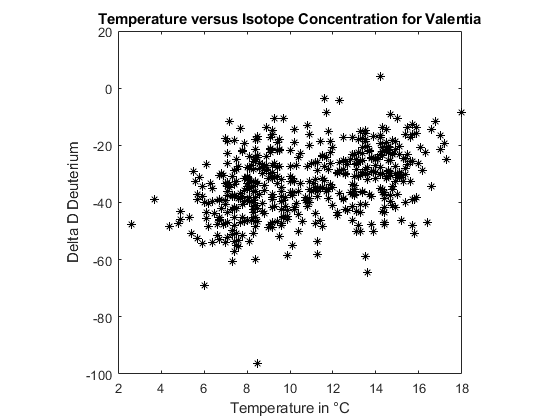

The resulting graph does not display and obvious correlation. This was to be expected, since our hypothesis is based on *average annual temperature*, not on the specific temperature at the time of precipitation. Instead of a weather dependence, it describes a correlation with the climate of a region, so in order to replicate the findings of our source paper, we need to compare geographically spread out data.

To do so, we chose six countries in different climate zones and uploaded their GNIP data into MATLAB, along with climate data from the World Bank Group Climate Change Knowledge Portal:[http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical](http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical)

s1 = readtable ('GeographicUK.xlsx'); % reading data from the specific Data File
s2 = readtable ('Greenland.xlsx');
s3 = readtable ('Spain.xlsx');
s4 = readtable ('Netherlands.xlsx');
s5 = readtable ('Norway.xlsx');
s6 = readtable ('Syria.xlsx');

t1 = readtable('GeographicUK_AAT.xls');
t2 = readtable('Greenland_AAT.xls');
t3 = readtable('Spain_AAT.xls');
t4 = readtable('Netherlands_AAT.xls');
t5 = readtable('Norway_AAT.xls');
t6 = readtable('Syria_AAT.xls');

We then calculated the mean and medium values of temperature and isotope precipitation for all three species. Note that while the data for deuterium and oxygen-18 is already given as delta D values, Tritium is given in TU (Tritium Units, one Tritium atom in 1018 hydrogen atoms), so we had to convert the tritium data into delta D before we display the results:

% means and medians of H2, H3, O18 and temperature for different locations
means=[mean(s1.H2,'omitnan'), mean(s1.H3,'omitnan'), mean(s1.O18,'omitnan'), mean(t1.tas,'omitnan')];
medians=[median(s1.H2,'omitnan'), median(s1.H3,'omitnan'), median(s1.O18,'omitnan'), median(t1.tas,'omitnan')];

means=[means;mean(s2.H2,'omitnan'), mean(s2.H3,'omitnan'), mean(s2.O18,'omitnan'), mean(t2.tas,'omitnan')];
medians=[medians;median(s2.H2,'omitnan'), median(s2.H3,'omitnan'), median(s2.O18,'omitnan'), median(t2.tas,'omitnan')];

means=[means;mean(s3.H2,'omitnan'), mean(s3.H3,'omitnan'), mean(s3.O18,'omitnan'), mean(t3.tas,'omitnan')];
medians=[medians;median(s3.H2,'omitnan'), median(s3.H3,'omitnan'), median(s3.O18,'omitnan'), median(t3.tas,'omitnan')];

means=[means;mean(s4.H2,'omitnan'), mean(s4.H3,'omitnan'), mean(s4.O18,'omitnan'), mean(t4.tas,'omitnan')];
medians=[medians;median(s4.H2,'omitnan'), median(s4.H3,'omitnan'), median(s4.O18,'omitnan'), median(t4.tas,'omitnan')];

means=[means;mean(s5.H2,'omitnan'), mean(s5.H3,'omitnan'), mean(s5.O18,'omitnan'), mean(t5.tas,'omitnan')];
medians=[medians;median(s5.H2,'omitnan'), median(s5.H3,'omitnan'), median(s5.O18,'omitnan'), median(t5.tas,'omitnan')];

means=[means;mean(s6.H2,'omitnan'), mean(s6.H3,'omitnan'), mean(s6.O18,'omitnan'), mean(t6.tas,'omitnan')];
medians=[medians;median(s6.H2,'omitnan'), median(s6.H3,'omitnan'), median(s6.O18,'omitnan'), median(t6.tas,'omitnan')];

According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of an isotope is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of the isotope to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\mathrm{ppm}$$
 

% the H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   % given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;

 Next we viewed our sample in form of scatterplots:

% plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     % H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

scatter(medians(:,4),medians(:,1));     % H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

scatter(means(:,4),means(:,2));     % H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

scatter(medians(:,4),medians(:,2));     % H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

scatter(means(:,4),means(:,3));     % O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

scatter(medians(:,4),medians(:,3));     % O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');

We can see the exact dependence as described in the reference paper for deuterium and oxygen-18, but no dependence for tritium. This might be because of the high tendency of tritium samples to get contaminated, it is stated on the IAEA WISER website that the measurements for tritium often return values significantly higher than expected.

To fully validate the temperature dependence, we needed to significantly increase our sample size. For this purpose, we developed a method to load whole folders of excel files into a cell array instead of uploading each table individually. The source directory has to be adjusted by each user, but this procedure enables us to sample almost the whole GNIP Database:

clear all  % clearing workspace and figure window for this section
clf

% the following path has to be adjusted for each computer!!!!!
source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/KarosContribution/';

% load all .xls files (the climate data) into one cell array
AATdata=loadfiles(source_dir,'*.xls');

% load all .xlsx files (the Isotope data) into one cell array
Isotopedata=loadfiles(source_dir,'*xlsx');

% calculate the means and medians for H2, H3, O18 and Temperature across all datasets
means=zeros(size(Isotopedata,1),4); % creates arrays full of zeros of the right size
medians=zeros(size(Isotopedata,1),4);

for i= 1:length(Isotopedata)
    
   activedata=Isotopedata{i,1};                    
   tempdata=AATdata{i,1};
   
   means(i,1)=mean(activedata.H2, 'omitnan');       % means for the isotopes
   means(i,2)=mean(activedata.H3, 'omitnan');
   means(i,3)=mean(activedata.O18, 'omitnan');
                                                
   medians(i,1)=median(activedata.H2, 'omitnan');   % medians for the isotopes
   medians(i,2)=median(activedata.H3, 'omitnan');
   medians(i,3)=median(activedata.O18, 'omitnan');
                    
   means(i,4)=mean(tempdata.tas, 'omitnan');        % means for temperatures
    
   medians(i,4)=median(tempdata.tas, 'omitnan');    % medians for temperatures
   
end  

% again, the H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   % given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;


% plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     % H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

scatter(medians(:,4),medians(:,1));     % H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

scatter(means(:,4),means(:,2));     % H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

scatter(medians(:,4),medians(:,2));     % H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

scatter(means(:,4),means(:,3));     % O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

scatter(medians(:,4),medians(:,3));     % O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');

The relationship only holds for average temperatures up to 15°C, so all datasets from countries with a higher annual temperature have to be sorted out:

% first, collect all mean and median values for temperatures below 15°C only
m=1;
n=1;
for k=1:length(means)
    if means(k,4)<=15
        behavedmeans(m,:)=means(k,:);        % means that theoretically follow the relationship
        m=m+1;
    end
    if medians(k,4)<=15
        behavedmedians(n,:)=medians(k,:);    % medians that theoretically follow the relationship
        n=n+1;
    end
end

%Plot these relevant regions
scatter(behavedmeans(:,4),behavedmeans(:,1));
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Approximately Linear Region for Climate Dependence of H2');

scatter(behavedmedians(:,4),behavedmedians(:,1));
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Approximately Linear Region for Climate Dependence of H2');

scatter(behavedmeans(:,4),behavedmeans(:,3));
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Approximately Linear Region for Climate Dependence of O18');

scatter(behavedmedians(:,4),behavedmedians(:,3));
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Approximately Linear Region for Climate Dependence of O18');

Next we want to find out whether means or medians provide the better linear regression and which Isotope most closely  abides a linear relationship. We use a function which inputs minimum two arrays of equal size and calculates a line of best fit for the first array against all the others in turn.

H2Fit=fitfunction(behavedmeans(:,4),behavedmeans(:,1),behavedmedians(:,1))
O18Fit=fitfunction(behavedmeans(:,4),behavedmeans(:,3),behavedmedians(:,3))
BestFit=fitfunction(behavedmeans(:,4),behavedmeans(:,1),behavedmedians(:,1),behavedmeans(:,3),behavedmedians(:,3))

figure(2)
plot(BestFit{1},behavedmeans(:,4), behavedmeans(:,3));
xlabel('Average Annual Temperature in °C');
ylabel('Delta D O18 (means)');
title('Best Fitting Linear Regression Line: O18 (means)');

Coefficients=BestFit{1}


The following computation is incomplete, it represents first efforts towards refining the above process and incorporating the mapping toolbox to represent data on different projections of the earth.

n=1;                % presetting variables to count iterations
m=1;
plotme=[];

for i=1:length(Isotopedata)     % this loop iterates over every loaded excel file, ergo every country
    
    activedata=Isotopedata{i};  
    latitudes=activedata.Latitude;
    longitudes=activedata.Longitude;
    H2=activedata.H2;           % for every excel table, latidudes, longitudes and the deuterium data is separated
    
    for j=1:(height(activedata))        % in this loop all isotope values are saved in one array as long as the geographical coordinates remain unchanged --> the data is separated by station
        holdisotopes(m)=H2(j);
        m=m+1;
        
        if j~=height(activedata)
            if (latitudes(j)~=latitudes(j+1))||(longitudes(j)~=longitudes(j+1))         % as soon as a new location provides data in the next row, all previously held data is saved and averaged if necessary
                plotme(n,:)=[latitudes(j), longitudes(j), mean(holdisotopes, 'omitnan')];
                holdisotopes=[];                            % this resets all hold variables
                m=1;
                n=n+1;
            end
        else
            plotme(n,:)=[latitudes(j), longitudes(j), mean(holdisotopes, 'omitnan')]; %When the table ends the same process as when the station changes is initiated
            holdisotopes=[];                        % also resetting container variables
            m=1;
            n=n+1;
        end
    end
end

plotme=rmmissing(plotme);           % plotme is a N-by-3 array connecting geographical coordinates to the monthly average deuterium precipitation

This code can be used to refine the temperature dependence analysis, it allows handling each station individually instead by country. Furthermore, the geolocated isotope values can be projected onto the earth with the mapping toolbox. First familiarisations with the toolbox can be seen below:

worldmap('World');
load coastlines;
plotm(coastlat,coastlon,'k');

geoshow(plotme(:,1),plotme(:,2),'DisplayType','point');
title('Locations of all GNIP Stations')

## **  3. Reproduction and Generalisation of the Code for the Graph of Average Deuterium Abundance In Precipitation for Different Intervals of Monthly Averages Precipitation Rates**

To reproduce and generalise the code which could be then further applicable to different regions as well, the plot from page 3714: $\delta \mathrm{D}$ vs. precipitation rate per day:

[5]* G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017*

was replotted.

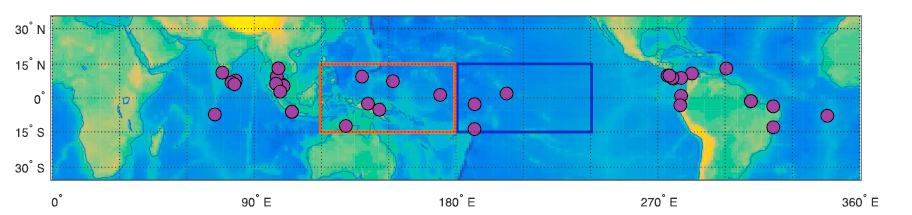

The data from IAEA WISED database for West and East Pacific was donwloaded accordingly:

**West:** (15° N - 15° S, 120° E - 180° E): Darwin, Jayapura, Madang, Tarawa, Truk, Yap

**East**: (15° N - 15° S, 180° E - 240° E): Apia, Canton Island, Christmas Island,

and imported to MATLAB. Readtable function was again used to easily extract data from downloaded Excel files, and the data was sorted chronologically using a sorting function (used in 1)).

clear all
clf
% WEST
wt1 = 'WDarwin.xlsx'; % Darwin
wt2 = 'WJayapura.xlsx'; % Jayapura
wt3 = 'WMadang.xlsx'; % Madang
wt4 = 'WTarawa.xlsx'; % Tarawa
wt5 = 'WTruk.xlsx'; % Truk
wt6 = 'WYap.xlsx'; % Yap

% EAST
et1 = 'EApia.xlsx'; % Apia
et2 = 'ECanton_Island.xlsx'; % Canton Island
et3 = 'EChristmas_Island.xlsx'; % Christmas Island
% % WEST
w1 = readtable (wt1);
w2 = readtable (wt2);
w3 = readtable (wt3);
w4 = readtable (wt4);
w5 = readtable (wt5);
w6 = readtable (wt6);

% EAST
e1 = readtable (et1);
e2 = readtable (et2);
e3 = readtable (et3);

To find general trends for these two areas (East and West), all data has to be concatenated first. To do this, the comment column was removed, as some of the downloaded station data had no data in this column, and so the column did not exist in the data when converted to a table. This only affected the data for West, so the comment column was removed from this data. However, when the section was run again without re-importing the western datasets, MATLAB did not understand the non-existence of this variable. Therefore, this process is done only if the data actually exists (if it exists for the first one, it is assumed that it exists for all).

A=any(strcmp('Comment',fieldnames(w1)));
B=any(strcmp('Comment',fieldnames(w2)));
C=any(strcmp('Comment',fieldnames(w3)));
D=any(strcmp('Comment',fieldnames(w4)));
E=any(strcmp('Comment',fieldnames(w5)));
F=any(strcmp('Comment',fieldnames(w6)));
ABCDEF=[A,B,C,D,E,F];
if any(ABCDEF) == 1
w1.Comment=[];
w2.Comment=[];
w3.Comment=[];
w4.Comment=[];
w5.Comment=[];
w6.Comment=[];
end

Also, some figures were set to refer back to a certain graph when specifying certain properties and data.

wFull=[w1;w2;w3;w4;w5;w6]; % concatenating the data from the various western stations
eFull=[e1;e2;e3]; % doing the same for east

figureNumScatter=10;
figureNumBins=20; 
% setting figure numbers for the two graphs

The loop was  used to plot the graphs twice, switching between East and West each time.

for j=[1,2]
 if j==1
     % for the Eastern Loop
     s=eFull;
     pointColour='xblack';
     barColour='blue';
     
 else
     % Western loop
     s=wFull;
     pointColour='.red';
     barColour='yellow';
     
 end

Next, the relevant data was retrieved. As the precipitation per day was supposed to be plotted, and months are different lengths, the number of days for the period when each reading was taken over was calculated, and this fact was further used to determine the average precipitation per day. Note that this had to be done via dividing total precipitation by number of days, as there was not any more temporal resolution than this.

% retrieving relevant data
d=datenum(s.Date,'yyyy-mm-dd');
H3=s.H3;
H2=s.H2;
O18=s.O18;

% days in month
numdays=(datenum(s.EndOfPeriod, 'yyyy-mm-dd')- datenum(s.BeginOfPeriod,'yyyy-mm-dd')+1);

% precipitation per day
pppday=s.Precipitation./numdays;

First, the scatter plot was plotted to visualize the unbinned data and to decide on the bin size.

% see a scatter plot of the data
figure(figureNumScatter)
hold on
plotObjectpppD(j)=plot(pppday,H2,pointColour);
title('Delta Deuterium vs. Precipitation Rate: Scatter plot')
hold off
xlabel('Precipitation rate (mm per day)')
ylabel('\delta D')

The original graph was plotted using bins of five with the final bin stretching to infinity.

% deciding our bin sizes
Edges=[0,5,10,15,20,Inf];

To do these steps,  the $\delta D$ data must have been discretized by its relevant precipitation per day data.

% finding out which deltaH2s fall in each ppt/day
[pppdaybin,Edge]= discretize(pppday,Edges);

% pppdaybin = which 'bin' each pppday in the array falls in
% to get the array of deltaH2 for each bin

Next, the loop was used in order to sparate out each binned set of data:

for i=1:(length(Edge)-1)
    
% using a structure as it is easier to use with loops
% making the struct separated by bin

H2binned(i).H2=H2(pppdaybin == i);
end

And another loop was used in order to find the means for each bin:

for i=1:(length(Edge)-1)
% finding the mean of these binned deltaH2 (along with the standard deviations)
    H2binned(i).mean = nanmean(H2binned(i).H2);
    H2binned(i).error = nanstd(H2binned(i).H2);
end

Whilst structures generally work more quickly with loops, arrays are slightly easier to do basic data manipulation with, so the data is was converted back into an array.

for i=1:(length(Edge)-1)
% switching these back to an array, so we can more conveniently use this data (ouside of loops)
    H2binnedmeans(i)=H2binned(i).mean;
    %here we use the standard error, as opposed to just the standard deviation of the dataset
    H2binnedmeanstandarderror(i)=(H2binned(i).error)./sqrt(length(H2binned(i).H2));
end

The original graph was reproduced plotting the mean $\delta \mathrm{D}$ binned, versus the midvalue of each bin. Note that for the last bin, the first bins midvalue was added to the beginning of the last bins first edge.

To find the midvalue:

% getting an array of the midvalues and creating an array of the start and end points of each bin, and then mean them

MidEdge(1,:)=Edge(1:(length(Edge)-1));
MidEdge(2,:)=Edge(2:length(Edge));
MidEdge=mean(MidEdge);
% redefining the mid edge for the final bin
MidEdge(length(Edge)-1)=MidEdge(1)+Edge(length(Edge)-1);


Finally, the bar function was used to produce similar bars as in the original graph. For the bars to not overlay each other, their position was adjusted depending on which loop cycle the code is on.

% plotting the graph, and use 'bar' function to plot as bars (as in the original paper)

if j==1
% shifting the bars for the first loop (East) to the negative
    MidEdgeShift=-1;
else
% and the bars for the second loop (West) to the positive
    MidEdgeShift=1;
end 
% plotting a bar graph
figure(figureNumBins)

To make the plot look little 'prettier':

% including earlier calculated shift
pointPosn=MidEdge+MidEdgeShift;
hold on

% creating a bar object so we can edit its properties
b(j)=bar(pointPosn,H2binnedmeans);

% adjust its width to allow us to see both bars at once, 
% and differentiate the colours we picked earlier
b(j).BarWidth=0.4;
b(j).FaceColor=barColour;
% to include errors, so we create an error bars object, and plot on the same graph
e=errorbar(pointPosn,H2binnedmeans,H2binnedmeanstandarderror);
% We remove the line and points of this 'second' graph, as we only want the error bars
e.LineStyle='none';
e.Marker='none';

At the end, all necessary details for the graph (title, axes labels, etc.) were included.

title ('Delta Deuterium vs. Precipitation Rate: Bar Graph')

xlabel('Precipitation rate (mm per day)')
ylabel('\delta D (per mil)')
xticklabels(Edges)
xlim([0,25])
ylim([-60,10])
grid on
hold off

end
legend (b,'Eastern', 'Western', 'Location', 'northeast' )
legend (plotObjectpppD,'Eastern', 'Western')


The next step was to repeat the same analysis for other isotopes, the UK and other geographic regions, i.e. Ireland.

The similar code was used, in a separate function file, to produce similar results for the UK, and identify any similar trends; however, as the UK lies in a different climate zone, some differences are expected to be seen.

ukgraphsfunction('GeographicUK.xlsx');

Finally, the larger of the British Isles (Britain and Ireland) were compared to see if there were any significant differences, potentially due to geographic positioning.

BIgraphsfunction('GeographicUK.xlsx','Ireland.xlsx')

**2) Investigation of a Correlation between Temperature and Isotope Precipitation**

Functions used in this script. They could be moved to an external file.

function bestfit=fitfunction(X,varargin)    % fitfunction accepts a variable number of input arguments
    
    gof=zeros(length(varargin),1);          % create an empty array to hold the coefficients of determination for later comparison
    
    for i=1:length(varargin)                % for every given possible y-value dataset...
        [~, gofi]=fit(X,varargin{i},'poly1');   % ...a 1st degree polynomial is fitted...
        gof(i)=gofi.rsquare;                % ... and the coeffitient of determination is retained
    end
    
    [bestgof, gofnb]=max(gof);              % the y-value dataset which provides the highest R² (--> the best fit) is determined
    coefficients=fit(X,varargin{gofnb},'poly1'); % calculate the coefficients for the linear equation describing the best fit
    
    bestfit={coefficients,bestgof,gofnb+1};   % the function outputs the best fit coefficients, the corresponding R² and the number of the input variable that provides the best fit
end

function loadedfiles=loadfiles(filepath, filextension)  % the complete file path and file extension are needed
    
source_files = dir(fullfile(filepath, filextension));   % the fullfile function merges file name fragments and the dir function lists all files the thereby specified folder which have the given extension
loadedfiles=cell(size(source_files));                   % precreate an empty cell array for all files to be loaded
      
    for i = 1:length(source_files)
      loadedfiles{i} = readtable(fullfile(filepath, source_files(i).name));  % one by one, every excel file identified above is loaded into Matlab using the readtable function
    end
end